clear all
clc
format long
numProves = 30;
tic
%Evaluate the GEPSO a number of "numProves" times
parfor i = 1:numProves 
    tic
        PSO_J(i, 0.001);
    tf = toc;
    disp("Proceso " + num2str(i))
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
Proceso 3
Proceso 1
Proceso 2
Proceso 4
Proceso 5
Proceso 6
Proceso 14
Proceso 12
Proceso 11
Proceso 10
Proceso 13
Proceso 9
Proceso 8
Proceso 16
Proceso 7
Proceso 15
Proceso 18
Proceso 17
Proceso 19
Proceso 22
Proceso 21
Proceso 20
Proceso 23
Proceso 24
Proceso 25
Proceso 26
Proceso 27
Proceso 28
Proceso 29
Proceso 30


tfProc = toc

tfProc =      1.461795469900000e+03


%Get the statistics of the results
p = load("process_" + num2str(1) + ".mat");

for i = 2:30
    p(i) = load("process_" + num2str(i) + ".mat");
end
p(:).JgBest

ans =    4.955951069368800


ans =    4.953211939315706


ans =    4.954349216340312


ans =    4.953722781841513


ans =    4.955312943253741


ans =    4.956249293702479


ans =    4.954309446865455


ans =    4.955270542389584


ans =    4.956790296848835


ans =    4.953795704808412


ans =    4.954523348980828


ans =    4.955831786366386


ans =    4.954653218605872


ans =    4.955471862826216


ans =    4.957142188996599


ans =    4.955703635589146


ans =    4.955629212545769


ans =    4.955575534211426


ans =    4.953674758289688


ans =    4.952519743980861


ans =    4.954669464382810


ans =    4.955988071700012


ans =    4.955136377659597


ans =    4.954775721890761


ans =    4.955075023518532


ans =    4.954138544358416


ans =    4.956725469397712


ans =    4.955302625146963


ans =    4.955841012789289


ans =    4.953564676876461


[minJ, idMinJ] = min([p(:).JgBest])

minJ =    4.952519743980861


idMinJ =     20


resG = p(idMinJ).gBest

resG =    5.880250638258114   1.024354519728830  37.730842699401919


meann = mean([p(:).JgBest])

meann =    4.955030183761606


mediann = median([p(:).JgBest])

mediann =    4.955203460024590


dvstd = std([p(:).JgBest])

dvstd =    0.001109721531157



save("test1")

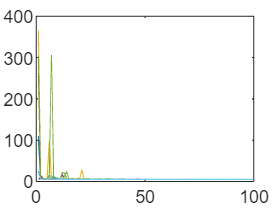

%graphs the behavior of the particles in each dimention
clf
plot(JHist')

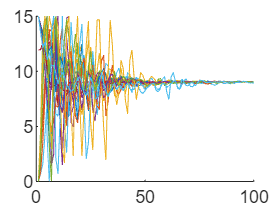

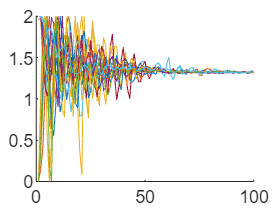

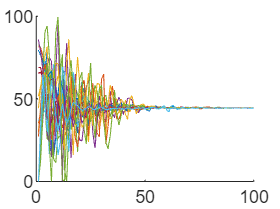


for j = 1:nVar
    figure;
    hold on
    for i = 1:nP
        plot(reshape(zHist(i, j, :), 1, nIt))
        % legend
    end
end

%graphs the behavior of the dynamic system
close all
tic
[J, y, x1q, e2fv, rv, rpv, uVal, duVal, t] = testFunPD(resG);
toc

Elapsed time is 0.252796 seconds.


J

J =    4.953211939315706


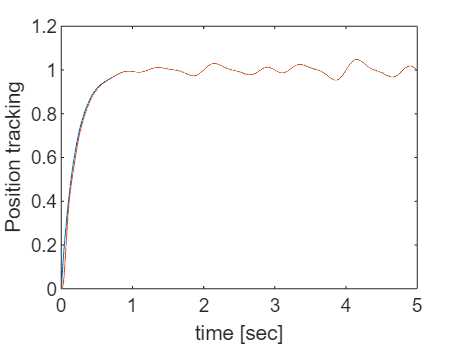


%Position tracking
figure
plot(t, rv);
hold on
plot(t, x1q);
xlabel("time [sec]");
ylabel("Position tracking");

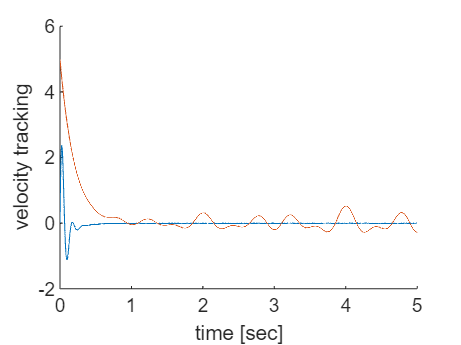


figure
hold on
plot(t, e2fv);
plot(t, rpv)
xlabel("time [sec]");
ylabel("velocity tracking");

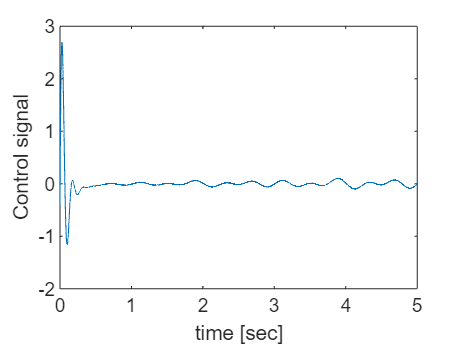


figure
plot(t, uVal);
xlabel("time [sec]");
ylabel("Control signal");

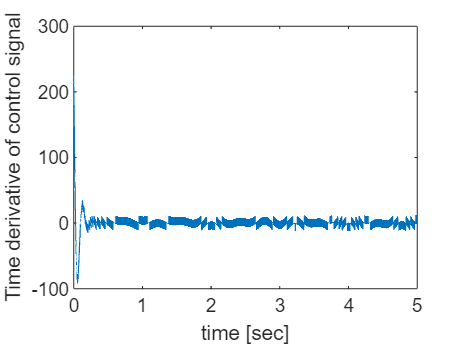


figure
plot(t(1:end-1), duVal);
xlabel("time [sec]");
ylabel("Time derivative of control signal");